# Panda Map Column

## Grid

grid = OctoGrid(2,2,2,10);

% add column
grid.addBox(0.9,1.25,0,0.2,0.2,2)

## Robot

% robot base transformation
Tbase = [cos(pi/2) -sin(pi/2) 0 0;
     sin(pi/2) cos(pi/2)  0 0;
     0          0           1 0;
     0          0           0 1]*eye(4);
Tbase(1:3,4) = [1,1,0]';

% set joints positions
joints = [0 0 0 0 0 0 0];

[robot_transforms] = GeometricPandaMATLAB(joints, Tbase);

## Show

% display
grid.showGridVol3D(grid.grid,'floor',true)
hold on
axis equal
showPanda(robot_transforms,10)
hold off

## Generate trajectory

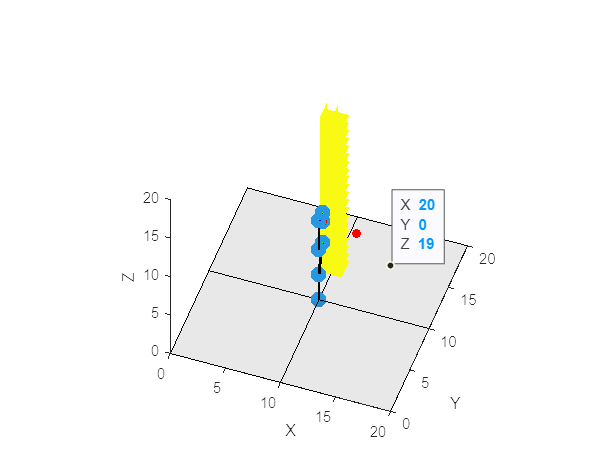

% trajectory generation points (xyz position, xyz angles)
control_points = [1 1.088 0.926 0 0 0;
                  1.2 1.4 0.5 0 0 0];

% Multiply the coordinates by 10 to scale the points
x = control_points(:, 1) * 10;
y = control_points(:, 2) * 10;
z = control_points(:, 3) * 10;

% display points
hold on

% Create a scatter plot with solid red points
scatter3(x, y, z, 'filled', 'MarkerFaceColor', 'red');